%Name: Martins Davis Bernhards 
%Student number: 552135
%Assignments week 3 


%Assignment 1

x = [1:1:10];
sum = squaredSum(x)

sum = 385

%Assignment 2

R = [20, 24, 27, 50, 32];
Rv = replacementResistance(R)

Rv = 5.5570

%Assignment 3

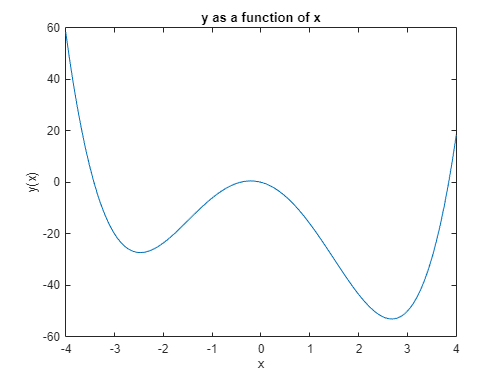

quadraticEquation(-3);
quadraticEquation(5);

x = linspace(-4,4,100);
y = quadraticEquation(x);

figure
plot(x,y);
title('y as a function of x');
xlabel('x');
ylabel('y(x)');

%Assignment 4

a = [1, 2, 4];
b = [2, -3, 1];

[y, txt] = calculateAngle(a, b)

y = 1.5708

txt = 'OK'

%Assignment 5

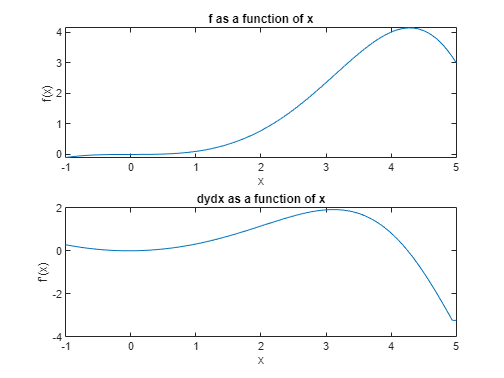

x = linspace(-1,5,100);
y = x .* sin(x.^2/10);
dydx = derivative(x, y);

figure
subplot(2,1,1);
plot(x, y);
title('f as a function of x');
xlabel('x');
ylabel('f(x)');

subplot(2,1,2);
plot(x, dydx);
title('dydx as a function of x');
xlabel('x');
ylabel('f''(x)');

%Assignment 6

% Manual calculation for Integral (x^2 + 4x)dx in range 5 to 2
% x^3/3 + 2*x^2  find the anti-derivative

% f(5) = 125/3 + 50 = 275/3
% f(2) = 8/3 + 8 = 32/3

% f(5) - f(2) = (273-32)/3 = 243/3 = 81
% answer is: 81

x_min = 2;
x_max = 5;
number_of_trapeziums = 1;

delta_x = (x_max-x_min)/number_of_trapeziums;
x = x_min:delta_x:x_max;
f_x = x.^2 + 4*x;
total_area1 = trapz(x,f_x) % 85.5 too big

total_area1 = 85.5000


number_of_trapeziums = 2;

delta_x = (x_max-x_min)/number_of_trapeziums;
x = x_min:delta_x:x_max;
f_x = x.^2 + 4*x;
total_area2 = trapz(x,f_x) % 82.1250 closer but also too big

total_area2 = 82.1250


number_of_trapeziums = 99;

delta_x = (x_max-x_min)/number_of_trapeziums;
x = x_min:delta_x:x_max;
f_x = x.^2 + 4*x;
total_area99 = trapz(x,f_x) % 81.0005 Basicaly the correct value, but differs a little bit

total_area99 = 81.0005


number_of_trapeziums = 999;

delta_x = (x_max-x_min)/number_of_trapeziums;
x = x_min:delta_x:x_max;
f_x = x.^2 + 4*x;
total_area999 = trapz(x,f_x) % 81 the correct answer, at least for first 4 decimal digits

total_area999 = 81.0000

%Assignment 7

x_min = 0;
x_max = 2;
number_of_trapeziums = 9;

delta_x = (x_max-x_min)/number_of_trapeziums;
x = x_min:delta_x:x_max;
f_x = 1 + cos(x.^2+1);
total_area10 = trapz(x,f_x) % 1.5882

total_area10 = 1.5882


number_of_trapeziums = 19;

delta_x = (x_max-x_min)/number_of_trapeziums;
x = x_min:delta_x:x_max;
f_x = 1 + cos(x.^2+1);
total_area20 = trapz(x,f_x) % 1.5757

total_area20 = 1.5757


number_of_trapeziums = 39;

delta_x = (x_max-x_min)/number_of_trapeziums;
x = x_min:delta_x:x_max;
f_x = 1 + cos(x.^2+1);
total_area40 = trapz(x,f_x) % 1.58730

total_area40 = 1.5730


number_of_trapeziums = 79;

delta_x = (x_max-x_min)/number_of_trapeziums;
x = x_min:delta_x:x_max;
f_x = 1 + cos(x.^2+1);
total_area80 = trapz(x,f_x) % 1.5723

total_area80 = 1.5723


number_of_trapeziums = 159;

delta_x = (x_max-x_min)/number_of_trapeziums;
x = x_min:delta_x:x_max;
f_x = 1 + cos(x.^2+1);
total_area160 = trapz(x,f_x) % 1.5722

total_area160 = 1.5722


number_of_trapeziums = 319;

delta_x = (x_max-x_min)/number_of_trapeziums;
x = x_min:delta_x:x_max;
f_x = 1 + cos(x.^2+1);
total_area320 = trapz(x,f_x) % 1.5721

total_area320 = 1.5721


number_of_trapeziums = 639;

delta_x = (x_max-x_min)/number_of_trapeziums;
x = x_min:delta_x:x_max;
f_x = 1 + cos(x.^2+1);
total_area639 = trapz(x,f_x) % 1.5721 With 640 the value for first 4 decimal digits doesn't change anymore

total_area639 = 1.5721

%Assignment 8

x_min = 0;
x_max = 2;
f_x = @(x) exp(1-x.^2);

result10 = simpson(f_x,x_min,x_max, 10) % 2.3977

result10 = 2.3977


result20 = simpson(f_x,x_min,x_max, 20) % 2.3977 Matches the previous value

result20 = 2.3977

%Assignment 9

f_x = @(x) exp(1-x.^2);
integral(f_x,0,2) % 2.3977

ans = 2.3977

%Assignment 10

f_x = @(x) x.^2+4*x;
integral(f_x,2,5) % 81

ans = 81.0000